# Population Predictive Coding: Laminar Cortical Circuit draft

->PPC-LCC

## 0. Initialization

clear;close all;clc;
PathToDynaSim = 'E:\'; % Change it based on your local path for dynasim 
cd(PathToDynaSim);
addpath(genpath('DynaSim'));
cd('\DynaSim\');

## 1.Neural circuit structure in Dynasim

PINH: Pyramidal-INterneuron Harmony circuit.

study_dir = 'dlModels/PPCLC1';

eqns={
  'dV/dt = Iapp*(linspace(0, 1, N_pop) > .5)*(t > t0 & t < t1) + @current + noise*randn(1, N_pop); noise = 0; t0 = 1000; t1 = 1500; Iapp = 0; V(0) = -70 + 7*randn(1, N_pop);'
};

% Circuit desc; 
% E (Pyramidal) 
% Ipv (local interneuron) 
% Isom (general interneuron) 
% 
% ->Circuit:
% 
% Populations:
% L2/3(s): E / Ipv / Isom 
% L4(m):   E / Ipv
% L5/6(d): E / Ipv / Isom 
% 
% Connections: 
% 
% 
% 


nES = 70;
nIF = 15;
nIS = 15;

gBase = 0.2;
gGABAslow = gBase / nIS; % Receptor conductances
gGABAfast = gBase / nIF;
gAMPA = gBase / nES;

tauGABAslow = 100 + randn(1); % Receptor synaptic time constants; SST->~10Hz ~(1/2t = 1/100)
tauGABAfast = 50 + randn(1); % PV->~100Hz (1/10)
tauAMPA = 50 + randn(1); % PY->~33.3Hz (1/30)

eNoise = 20;
fNoise = 20;
sNoise = 20;

cCoeff = 4; % 

kEE = ones(nES, nES) / cCoeff;
kEIf = ones(nES, nIF) / cCoeff;
kEIs = ones(nES, nIS) / cCoeff;

kIfE = ones(nIF, nES) / cCoeff;
kIfIf = ones(nIF, nIF) / cCoeff;
kIfIs = ones(nIF, nIS) / cCoeff;

kIsE = ones(nIS, nES) / cCoeff;
kIsIf = ones(nIS, nIF) / cCoeff;
kIsIs = ones(nIS, nIS) / cCoeff;

s=[];
s.populations(1).name='ES';
s.populations(1).size=nES;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'gNa',120,'gK',36,'noise',eNoise};

s.populations(2).name='INfast';
s.populations(2).size=nIF;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'gNa',120,'gK',36,'noise',fNoise};

s.populations(3).name='INslow';
s.populations(3).size=nIS;
s.populations(3).equations=eqns;
s.populations(3).mechanism_list={'iNa','iK'};
s.populations(3).parameters={'gNa',120,'gK',36,'noise',sNoise};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIfE};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA, 'netcon', kEIf};

s.connections(3).direction='INslow->ES';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kIsE};

s.connections(4).direction='ES->INslow';
s.connections(4).mechanism_list={'iAMPA'};
s.connections(4).parameters={'tauD',tauAMPA,'gAMPA',gAMPA, 'netcon', kEIs};

s.connections(5).direction='INslow->INfast';
s.connections(5).mechanism_list={'iGABAa'};
s.connections(5).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kIsIf};

s.connections(6).direction='INslow->INslow';
s.connections(6).mechanism_list={'iGABAa'};
s.connections(6).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kIsIs};

s.connections(7).direction='INfast->INslow';
s.connections(7).mechanism_list={'iGABAa'};
s.connections(7).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIfIs};

s.connections(8).direction='INfast->INfast';
s.connections(8).mechanism_list={'iGABAa'};
s.connections(8).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIfIf};

s.connections(9).direction='ES->ES';
s.connections(9).mechanism_list={'iAMPA'};
s.connections(9).parameters={'tauD',tauAMPA,'gAMPA',gAMPA/2, 'netcon', kEE};

RunDuration = 2000; % In ms (miliseconds)
vary = {'ES', 'Iapp', [0 1 2]};

data = dsSimulate(s, 'tspan', [0 RunDuration], 'downsample_factor', 10, ...
                     'solver', 'euler', 'dt', .01, ...
                     'compile_flag', 0, 'parallel_flag', 1, ...
                     'vary', vary, 'verbose_flag', 1);


PREPARING STUDY:
Creating study directory: E:\DynaSim\study_20240322145433
Creating data directory: E:\DynaSim\study_20240322145433\data
Creating results directory: E:\DynaSim\study_20240322145433\results
saving study file: E:\DynaSim\study_20240322145433\studyinfo.mat

PREPARING SOLVER:
Creating solver directory E:\DynaSim\study_20240322145433\solve\sim1
Changing directory to E:\DynaSim\study_20240322145433\solve\sim1
Saving params.mat

PREPARING SOLVER:

PREPARING SOLVER:
Creating solver directory E:\DynaSim\study_20240322145433\solve\sim3
Changing directory to E:\DynaSim\study_20240322145433\solve\sim3
Saving params.mat
Creating solver directory E:\DynaSim\study_20240322145433\solve\sim2
Changing directory to E:\DynaSim\study_20240322145433\solve\sim2
Saving params.mat
Creating solver file: E:\DynaSim\study_20240322145433\solve\sim2\solve_ode_20240322145434_420.m
Changing directory back to E:\DynaSim

SIMULATING MODEL:
Creating solver file: E:\DynaSim\study_20240322145433\solve\sim


Parallel simulations complete.



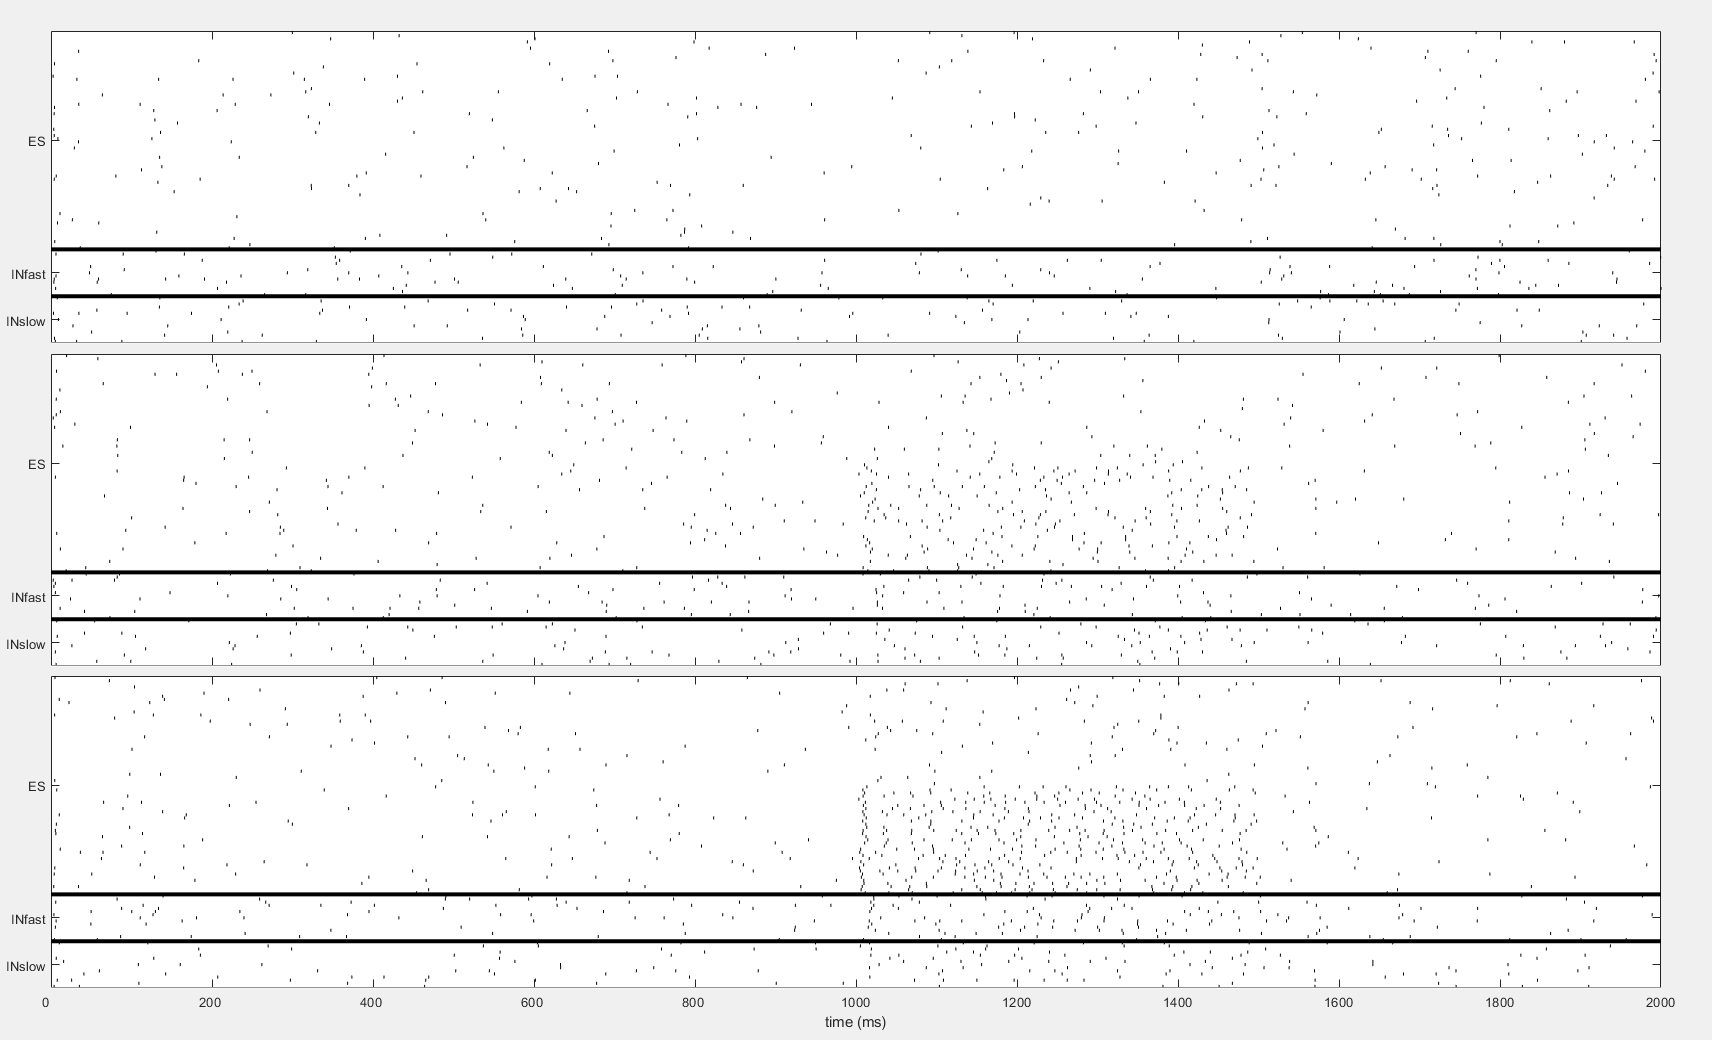

dsPlot(data, 'plot_type','raster');

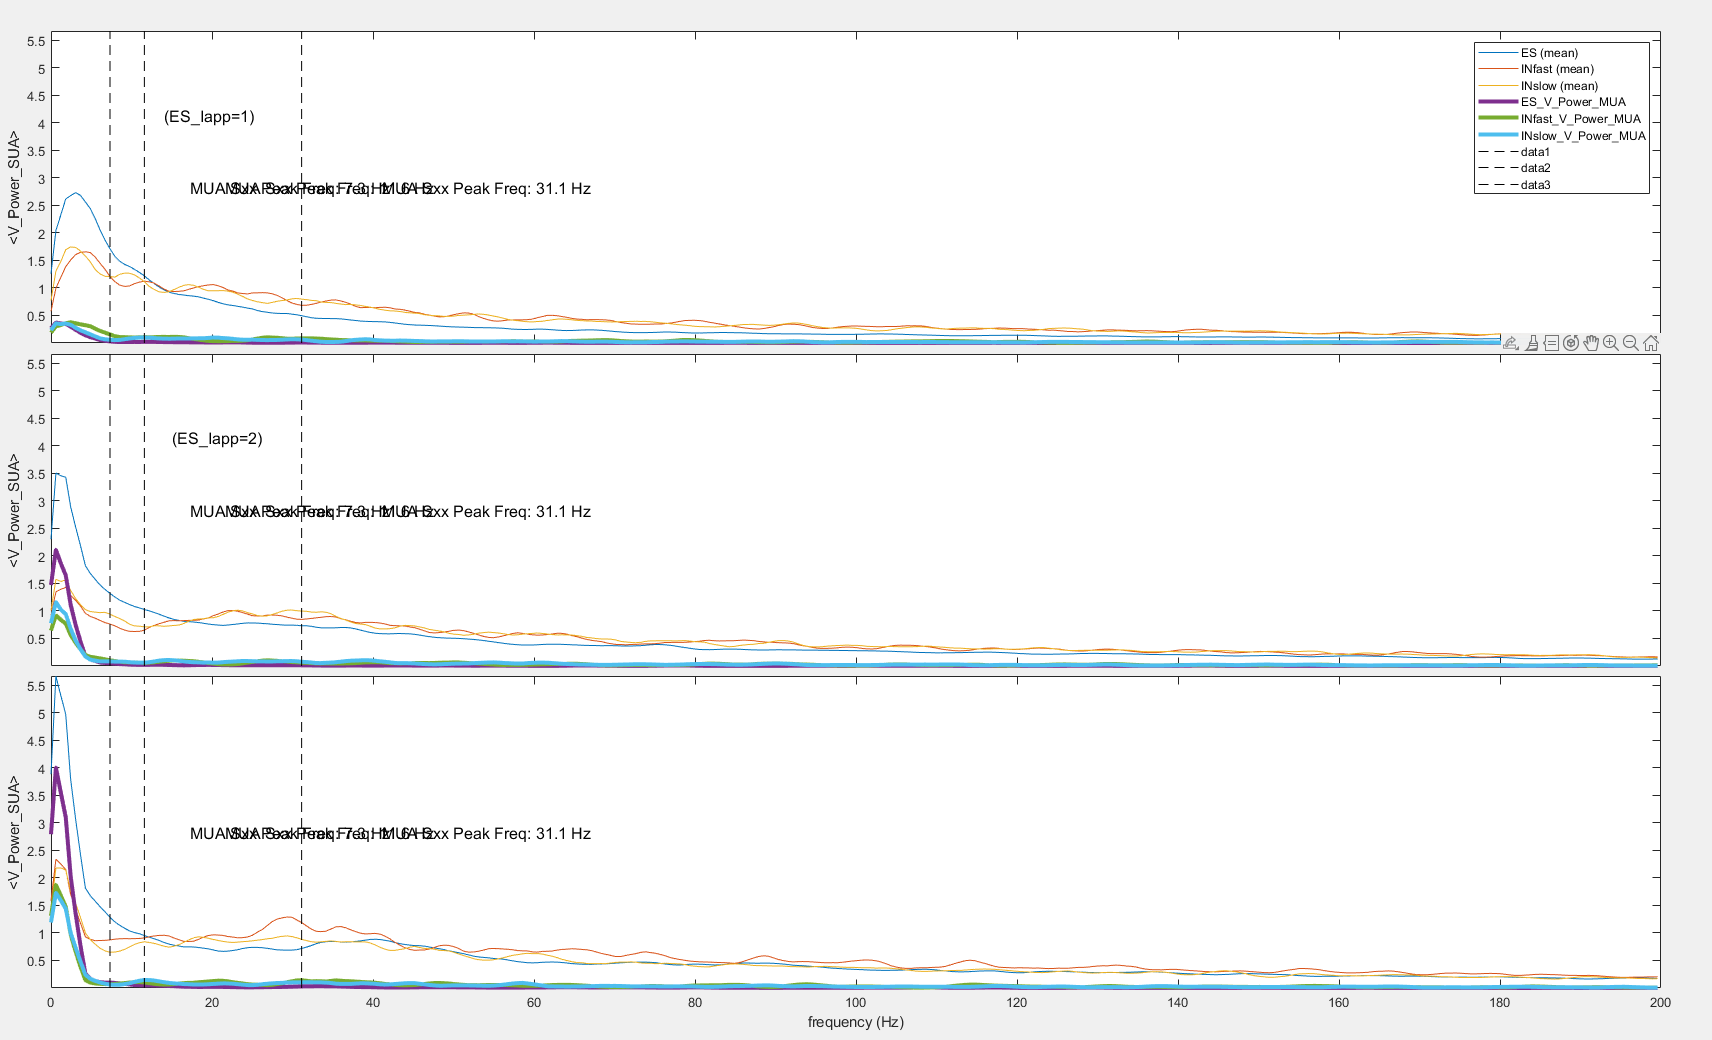

dsPlot(data, 'plot_type','power');

## 2. DynaLearn object initialization

dl = DynaLearn(s, study_dir, 'mex', 'PINO', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: E:\DynaSim\dlModels\P1
Creating data directory: E:\DynaSim\dlModels\P1\data
Creating results directory: E:\DynaSim\dlModels\P1\results
saving study file: E:\DynaSim\dlModels\P1\studyinfo.mat

PREPARING SOLVER:
Creating solver directory E:\DynaSim\dlModels\P1\solve\sim1
Changing directory to E:\DynaSim\dlModels\P1\solve\sim1
Saving params.mat
Creating solver file: E:\DynaSim\dlModels\P1\solve\sim1\solve_ode_20240322145711_955.m
Compiling file: E:\DynaSim\dlModels\P1\solve\sim1\solve_ode_20240322145711_955.m
            to: E:\DynaSim\dlModels\P1\solve\sim1\solve_ode_20240322145711_955_mex


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/P1/dlFile.mat".


- Loader function; if the model already exists.

id = 1;
DynaLearn.dlLoader(char("dlModels/P" + num2str(id)));

DL object loaded from dlModels/P1 
Params.mat file loaded from dlModels/P1 
--------
--->Constructing graph ... Done.

Reinitialized.


x = load("mstB2poGLO.mat").x;

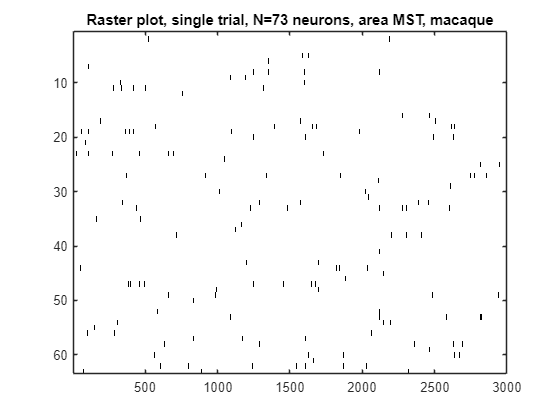

trial = 144;
aidx = mean(squeeze(x(trial, :, 1001:4000)), 2) > 0.001;
a = squeeze(x(trial, aidx, 1001:4000));
figure;
imagesc(1-a);colormap("gray");
title("Raster plot, single trial, N=73 neurons, area MST, macaque");

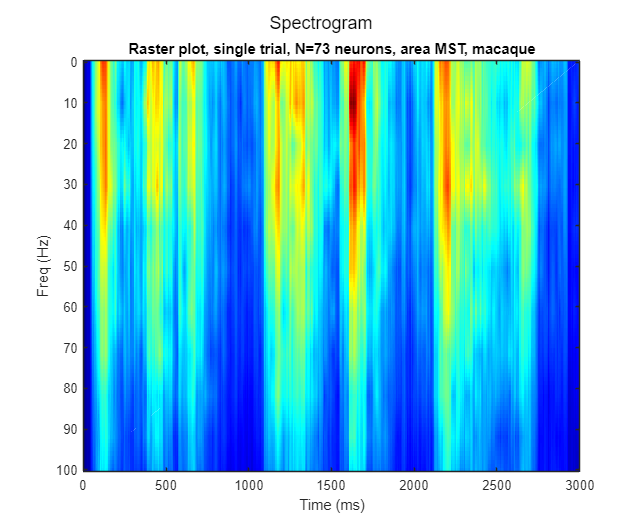

figure;
dlSpectrogramPlot(a, 100, 1, 95, 100, 1000);
title("Raster plot, single trial, N=73 neurons, area MST, macaque");

y1 = zeros(size(x, 1), size(x, 2), 100);
y2 = zeros(size(x, 1), size(x, 2), 100);

for i = 1:size(x, 1)

    for j = 1:size(x, 2)

        w = squeeze(x(i, j, 1001:2000));
        y1(i, j, :) = dlSpectrum(w, 1000, 100, 100);
        w = squeeze(x(i, j, 4001:5000));
        y2(i, j, :) = dlSpectrum(w, 1000, 100, 100);

    end

end

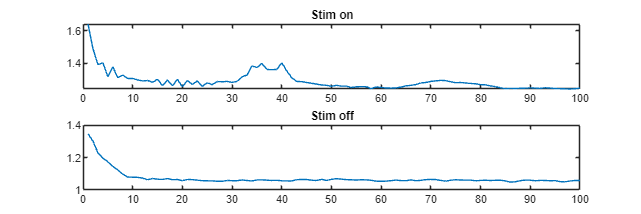

targetVspectrum1 = mean(squeeze(mean(y1, 1)), 1);
targetVspectrum2 = mean(squeeze(mean(y2, 1)), 1);
figure("Position", [0 0 1500 500]);
subplot(2, 1, 1);
plot(targetVspectrum1);
title("Stim on");
subplot(2, 1, 2);
plot(targetVspectrum2);
title("Stim off");

RunDuration = 2000;
[inp1, inp2] = dlOnOffInputs(RunDuration, 1000, 1500, 1);
dlInputParameters = {inp1, inp2}; % Null inputs (no external stimulation).
dlOutputParameters = {['ES', '_V'], 1:70, [1 RunDuration], 'afr'};
dlTargetParameters = {{'LogCor', 1, targetVspectrum1, 1e+3, 10, 100}, {'LogCor', 1, targetVspectrum2, 1e+3, 10, 100}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure

dlTrainOptions('dlBatchs') = 2;
dlTrainOptions('dlLambda') = 1e-4; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 100; % Total iterations 
dlTrainOptions('dlUpdateVerbose') = 1;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 10;
dlTrainOptions('dlTrainIncludeList') = "_netcon";
dlTrainOptions('dlUpdateMode') = 'Batch';

dlTrainOptions('dlMIDP') = 1;
dlTrainOptions('dlCheckpointCoefficient') = 1.1;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_netcon
---> INfast_INfast_iGABAa_netcon
---> _iAMPA_netcon
-->Excluded variable(s) on fitting: 
---> 
-->Restricted variable(s) on fitting: 
---> 
-->Synchronized variable(s) on fitting: 
---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (On)
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model error.
--->Reminder: you have choosen adaptive lambda but forgot to determine a lambda cap. default dlLambdaCap = 1.000000
   ->Total valid trials 168 (Total iterations for this model : 663

RunDuration = 3000;
[inp1, inp2] = dlOnOffInputs(RunDuration, 1000, 2000, .5);
dlInputParameters = {inp1, inp2}; % Null inputs (no external stimulation).
dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/P1/Optimal 
---->Optimal [Parallel]


Condition1



	->Single trial running: 
Updating parameters of dlModels/P1/solve > 

	-->Simulation outputs:     {[4.0161]}



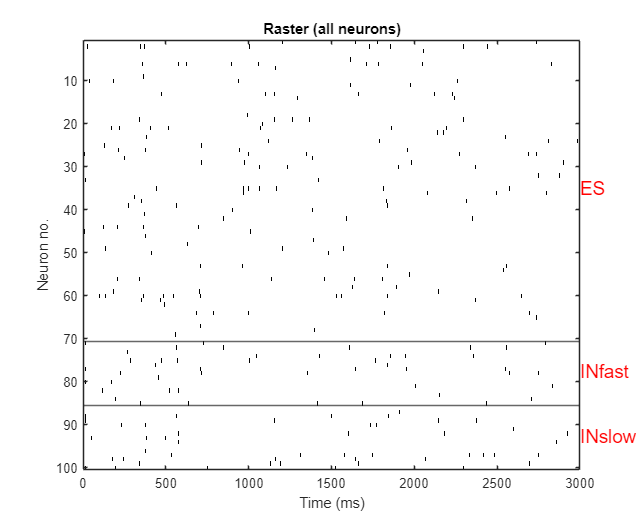

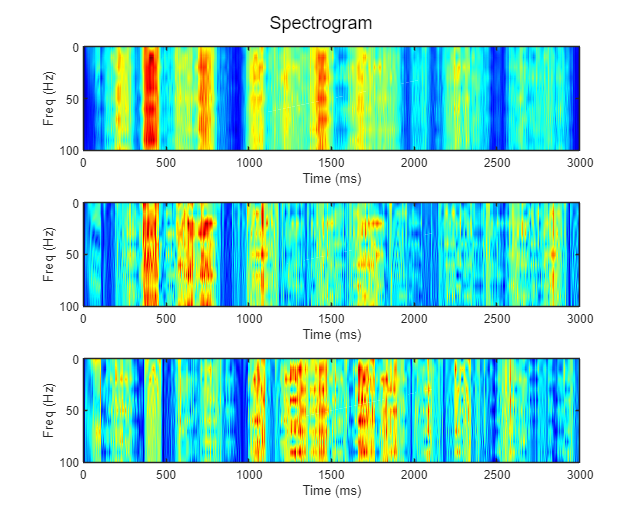

Condition2



	->Single trial running: 
Updating parameters of dlModels/P1/solve > 

	-->Simulation outputs:     {[4.7664]}



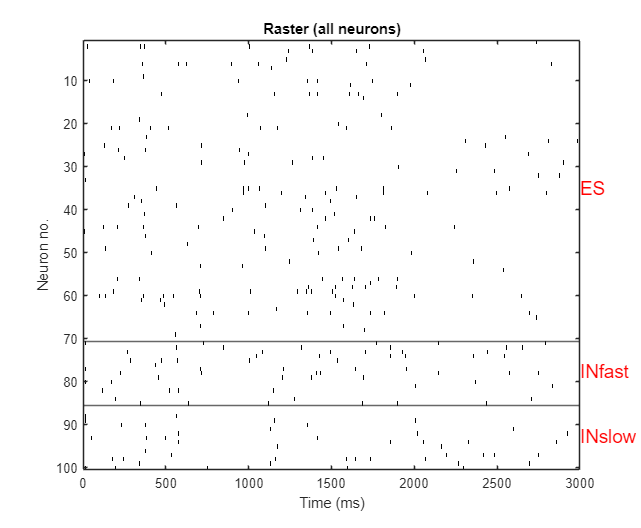

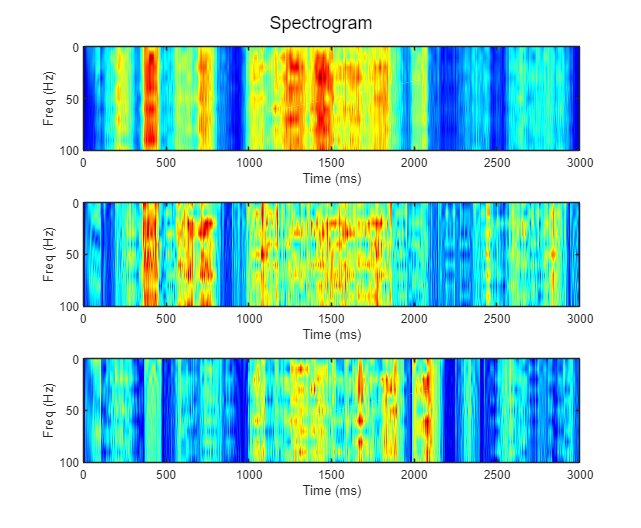

for i = 1:max(size(dlInputParameters, 2))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlRaster();
    dl.dlSpectrogram(100, 1, 95, 100);

end

a = dl.dlSignals;
a = (1 - a) > 4;
y = zeros(size(a));

for i = 1:size(a, 1)

    tempX = a(i, :);
    tempX = conv(tempX, exp(linspace(1, 0, 70)), "same");
    y(i, :) = tempX;

end

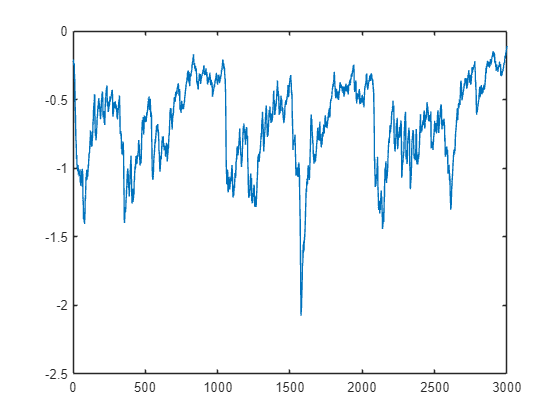

y = zeros(size(a));

for i = 1:size(a, 1)

    tempX = a(i, :);
    tempX = conv(tempX, exp(linspace(1, 0, 70)), "same");
    y(i, :) = tempX;

end

figure;
plot(linspace(0, 3000, 3000), -mean(y', 2));

## End